# Mapping Tutorial

# Naomi Jainarine

# Big Data - Spring 2024

## We will be creating a map of "sample sites" for a dredging project I am working on. This project was discussed in our group's proposal presentation.

The file we will be working with has the following columns:

sta = station ID

lat = latitude

lon = longitude

copepod_bef = copepod density before dredging

copepod_during = copepod density during dredging

copepod_after = copepod density after dredging

First, let's  upload our data. You must set a directory so matlab knows to use where to look for the ***package*** and ***file*** you are using. 

clear;
close ALL FORCE;

addpath(genpath('C:\Users\Naomi Jainarine\Documents\Dissertation\Dissertation Matlab files\add ons')); %package location
addpath 'C:\Users\Naomi Jainarine\Documents\Dissertation\Dissertation Matlab files\Dredging Impacts Interim Analyses' %file location

file_path= 'C:\Users\Naomi Jainarine\Documents\Dissertation\Dissertation Matlab files\Dredging Impacts Interim Analyses\cape_fear_station_names.csv';

% read table from csv
data_table= readtable(file_path);

%  access column by names
sta = data_table.sta;
lat = data_table.lat;
lon = data_table.lon;
cop_bef = data_table.copepod_bef

cop_bef = 1.0e+03 *

    0.1460
    0.1803
    0.5756
    1.0849
    0.2869
    1.0351
    2.8764
    0.1174
    0.1253
    0.1219


cop_dur = data_table.copepod_during

cop_dur =   125.2114
  444.8535
  160.0419
   77.0352
  241.4150
  145.7850
  994.1185
   73.4444
  214.2259
  352.2347


cop_aft= data_table.copepod_after

cop_aft =   481.5129
  200.7851
  895.1954
  409.1491
  237.8995
  336.2391
  697.9283
  251.1987
  278.2771
    8.9174


Now, let's make a map to show our sampling sites. We have to include the type of map projection we want. I chose the 'miller' map projection because it has specific lat and long limits and overlays the Global Self-consistent Hierarchical High-resolution Shorelines (GSHHS) coastline data to draw the land boundaries on the map.

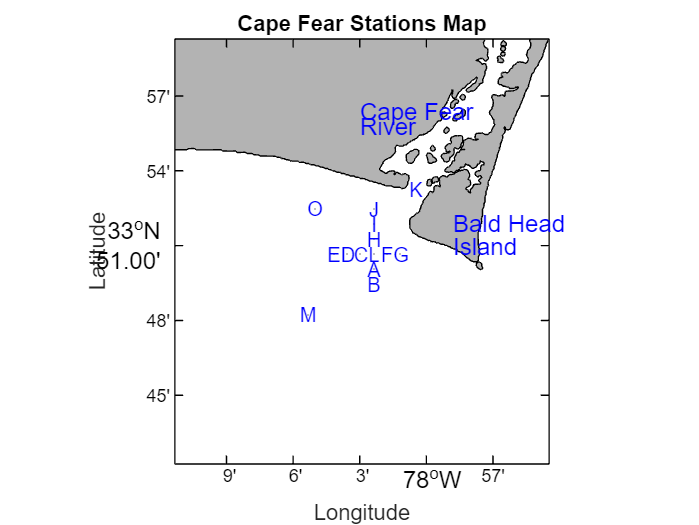

figure;
m_proj('miller','lon',[min(lon)-.1,max(lon)+.1],...  %this sets up our area of land, you can change the values '0.1' to zoom in and out
    'lat',[min(lat)-.1,max(lat)+.1]);
hold on;
m_gshhs_f('patch',[0.7 0.7 0.7]); % Changes the color of the land

% plot the station locations 
m_plot(lon, lat, 'o', 'MarkerSize', 0.1, 'MarkerFaceColor', 'white', 'MarkerEdgeColor', 'k');

% add station locations/lables
for i = 1:numel(sta)
    [x, y] = m_ll2xy(lon(i), lat(i));
    text(x, y, sta{i}, 'Color', 'blue', 'FontSize', 10, 'HorizontalAlignment', 'center');
end

% Adjusted m_grid parameters
m_grid('tickdir', 'in', 'linestyle', 'none', 'fontsize', 12, ...
    'xtick', floor(min(lon)-0.1):0.05:ceil(max(lon)+0.1), ...
    'ytick', floor(min(lat)-0.1):0.05:ceil(max(lat)+0.1), ...
    'ticklength', 0.02);

% Title and labels
title('Cape Fear Stations Map');
xlabel('Longitude');
ylabel('Latitude');
m_text(-77.98,33.865,'Bald Head','fontsize',12,'Color', 'blue');
m_text(-77.98,33.85,'Island','fontsize',12,'Color', 'blue');
m_text(-78.05,33.94,'Cape Fear','fontsize',12,'Color', 'blue');
m_text(-78.05,33.93,'River','fontsize',12,'Color', 'blue');

Great! We have a map! How can we use this mapping tool to visualize meaningful data? We can make a heatmap with biological data!  In our csv, I've included copepod density from before during and after dredging. Let's make a map for each of these dredging periods to see how it fluctuates.  

Before Dredging:

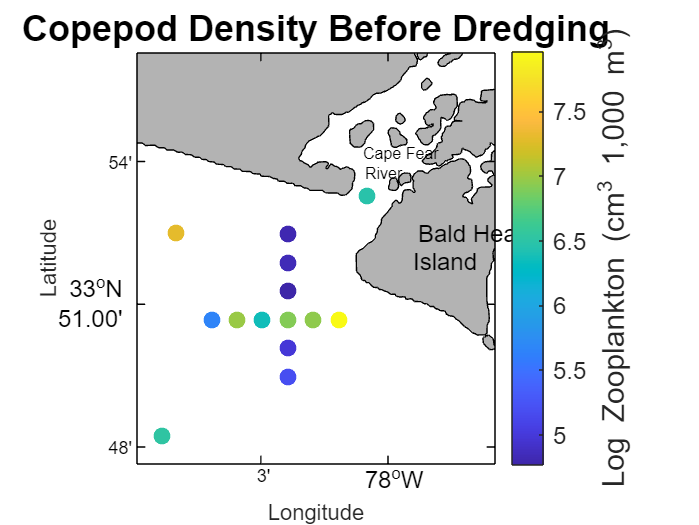

%set min and max values for heatmap
min_z=min(log(cop_bef));
max_z=max(log(cop_bef));
%% we are doing a log transformation on the data

figure;
m_proj('miller','lon',[min(lon)-.01,max(lon)+.05],...  %this sets up our area of land
    'lat',[min(lat)-.01,max(lat)+.05]);
hold on;
m_gshhs_f('patch',[0.7 0.7 0.7]); % Changes the color of the land

m_scatter(lon, lat,70, log(cop_bef),'filled'); 
c=colorbar; % Adds in a colorbar
caxis([min_z, max_z]); 
set(c,'fontsize',12); % Sets fontsize for the colorbar
ylabel(c,'Log Zooplankton (cm^3 1,000 m^-^3)','fontsize',15); % Label for the colorbar

% Adjusted m_grid parameters
m_grid('tickdir', 'in', 'linestyle', 'none', 'fontsize', 12, ...
    'xtick', floor(min(lon)-0.1):0.05:ceil(max(lon)+0.1), ...
    'ytick', floor(min(lat)-0.1):0.05:ceil(max(lat)+0.1), ...
    'ticklength', 0.02);

% Title and labels
title('Copepod Density Before Dredging','fontsize',18);
xlabel('Longitude');
ylabel('Latitude');
m_text(-77.988,33.875,'Bald Head','fontsize',12);
m_text(-77.99,33.865,'Island','fontsize',12);
m_text(-78.01,33.903,'Cape Fear','fontsize',8);
m_text(-78.009,33.896,'River','fontsize',8);

During Dredging

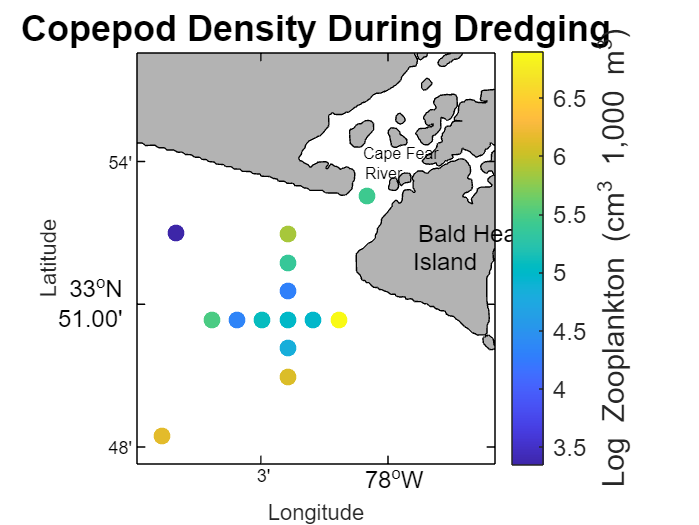

%set min and max values for heatmap
min_z=min(log(cop_dur));
max_z=max(log(cop_dur));
%% we are doing a log transformation on the data

figure;
m_proj('miller','lon',[min(lon)-.01,max(lon)+.05],...  %this sets up our area of land
    'lat',[min(lat)-.01,max(lat)+.05]);
hold on;
m_gshhs_f('patch',[0.7 0.7 0.7]); % Changes the color of the land

m_scatter(lon, lat,70, log(cop_dur),'filled'); 
c=colorbar; % Adds in a colorbar
caxis([min_z, max_z]); 
set(c,'fontsize',12); % Sets fontsize for the colorbar
ylabel(c,'Log Zooplankton (cm^3 1,000 m^-^3)','fontsize',15); % Label for the colorbar

% Adjusted m_grid parameters
m_grid('tickdir', 'in', 'linestyle', 'none', 'fontsize', 12, ...
    'xtick', floor(min(lon)-0.1):0.05:ceil(max(lon)+0.1), ...
    'ytick', floor(min(lat)-0.1):0.05:ceil(max(lat)+0.1), ...
    'ticklength', 0.02);

% Title and labels
title('Copepod Density During Dredging','fontsize',18);
xlabel('Longitude');
ylabel('Latitude');
m_text(-77.988,33.875,'Bald Head','fontsize',12);
m_text(-77.99,33.865,'Island','fontsize',12);
m_text(-78.01,33.903,'Cape Fear','fontsize',8);
m_text(-78.009,33.896,'River','fontsize',8);

After Dredging

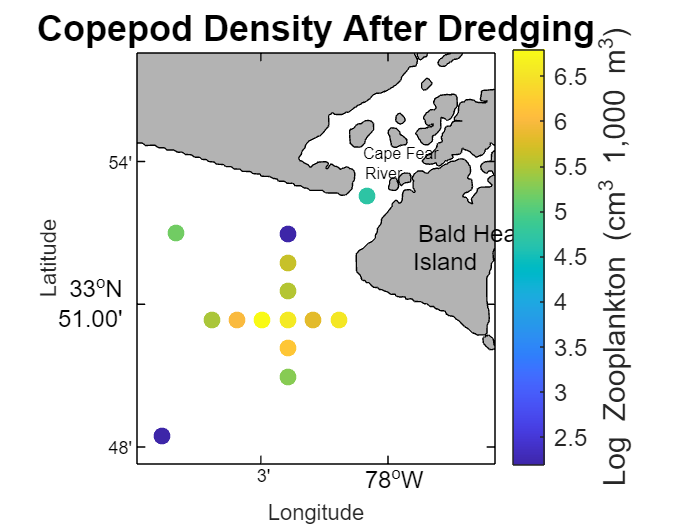

%set min and max values for heatmap
min_z=min(log(cop_aft));
max_z=max(log(cop_aft));
%% we are doing a log transformation on the data

figure;
m_proj('miller','lon',[min(lon)-.01,max(lon)+.05],...  %this sets up our area of land
    'lat',[min(lat)-.01,max(lat)+.05]);
hold on;
m_gshhs_f('patch',[0.7 0.7 0.7]); % Changes the color of the land

m_scatter(lon, lat,70, log(cop_aft),'filled'); 
c=colorbar; % Adds in a colorbar
caxis([min_z, max_z]); 
set(c,'fontsize',12); % Sets fontsize for the colorbar
ylabel(c,'Log Zooplankton (cm^3 1,000 m^-^3)','fontsize',15); % Label for the colorbar

% Adjusted m_grid parameters
m_grid('tickdir', 'in', 'linestyle', 'none', 'fontsize', 12, ...
    'xtick', floor(min(lon)-0.1):0.05:ceil(max(lon)+0.1), ...
    'ytick', floor(min(lat)-0.1):0.05:ceil(max(lat)+0.1), ...
    'ticklength', 0.02);

% Title and labels
title('Copepod Density After Dredging','fontsize',18);
xlabel('Longitude');
ylabel('Latitude');
m_text(-77.988,33.875,'Bald Head','fontsize',12);
m_text(-77.99,33.865,'Island','fontsize',12);
m_text(-78.01,33.903,'Cape Fear','fontsize',8);
m_text(-78.009,33.896,'River','fontsize',8);

Okay, so we have an idea of how copepod abundance changed visually. **Are these visual changes *****statisitically***** significant?** Let's run a quick ANOVA statisical test.

What is Analysis of Variance (ANOVA)?

"ANOVA stands for Analysis of Variance. It is a statistical method used to analyze the differences between the means of two or more groups or treatments. It is often used to determine whether there are any statistically significant differences between the means of different groups."

Infomation taken from : [https://www.analyticsvidhya.com/blog/2018/01/anova-analysis-of-variance/](https://www.analyticsvidhya.com/blog/2018/01/anova-analysis-of-variance/)

A new csv will be used. It contains the same exact data, but it is formatted differently. 


file_path2= 'C:\Users\Naomi Jainarine\Documents\Dissertation\Dissertation Matlab files\Dredging Impacts Interim Analyses\cape_fear_copepod_anova.csv';

% read table from csv
data_table2= readtable(file_path2);

%  access column by names
sta = data_table2.sta;
lat = data_table2.lat;
lon = data_table2.lon;
cop_den = data_table2.copepod_density

cop_den = 1.0e+03 *

    0.1460
    0.1803
    0.5756
    1.0849
    0.2869
    1.0351
    2.8764
    0.1174
    0.1253
    0.1219


dre_per = data_table2.dredge_period

dre_per = 42×1 cell array
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'before'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'during'}
    {'after' }
    {'after' }




% Perform ANOVA
[p, tbl, stats] = anova1(cop_den, dre_per, 'off'); % 'off' to suppress display

% Display ANOVA table
disp('ANOVA Table:');

ANOVA Table:


disp(tbl);

    {'Source'}    {'SS'        }    {'df'}    {'MS'        }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[1.7326e+06]}    {[ 2]}    {[8.6628e+05]}    {[  3.6275]}    {[  0.0362]}
    {'Error' }    {[9.0748e+06]}    {[38]}    {[2.3881e+05]}    {0×0 double}    {0×0 double}
    {'Total' }    {[1.0807e+07]}    {[40]}    {0×0 double  }    {0×0 double}    {0×0 double}




% Interpret the results
if p < 0.05
    disp('The means are significantly different (reject null hypothesis).');
else
    disp('The means are not significantly different (fail to reject null hypothesis).');
end

The means are significantly different (reject null hypothesis).
